% Clear workspace
clear; clc;

% 1. Define variables and boundary conditions
a = 0; 
b = 2; 
alpha = 0; % y(0) = 0
beta = 4;  % y(2) = 4

% 2. Define functions based on standard form: y'' + p*y' + q*y = r
p = @(x) (x.^2) ./ (x.^3 + 1); 
q = @(x) (-4.*x) ./ (x.^3 + 1); 
r = @(x) 2 ./ (x.^3 + 1); 

% Step sizes to test
h_values = [0.5, 0.2, 0.1]; 
colors = {'g-o', 'r-s', 'm-^'};

figure; hold on;
fprintf('   h    |  x      | Numerical y | Comparison\n');

   h    |  x      | Numerical y | Comparison


fprintf('--------------------------------------------\n');

--------------------------------------------



for k = 1:length(h_values)
    h_curr = h_values(k);
    
    % n = (interval_length / h) - 1
    n = round((b - a) / h_curr) - 1;

    % 3. Call the function
    [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n);

    % Find value closest to mid-point (x=1.0) for comparison
    [~, idx] = min(abs(x - 1.0));
    fprintf('%6.2f  | %6.1f  | %10.6f  | (at x=%.1f)\n', ...
            h_curr, x(idx), y(idx), x(idx));

    % 6. Plot results
    plot(x, y, colors{k}, 'LineWidth', 1.5, 'MarkerSize', 6, ...
         'DisplayName', ['h = ', num2str(h_curr)]);
end

  0.50  |    1.0  |   1.000000  | (at x=1.0)
  0.20  |    1.0  |   1.000000  | (at x=1.0)
  0.10  |    1.0  |   1.000000  | (at x=1.0)


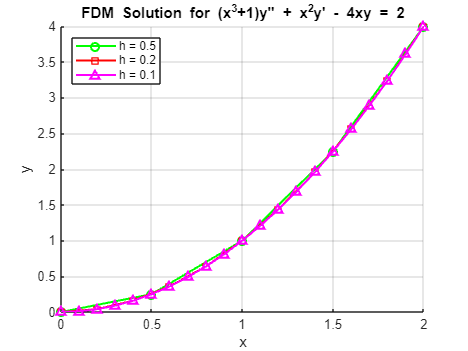


% Formatting
legend('Location', 'northwest');
xlabel('x'); ylabel('y');
title('FDM Solution for (x^3+1)y'''' + x^2y'' - 4xy = 2');
grid on;


%% --- Function Definition (Remains the same) ---
function [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n)
    h = (b - a) / (n + 1);
    x = linspace(a, b, n + 2)'; 
    x_inner = x(2:end-1);

    A = zeros(n, n);
    B = zeros(n, 1);

    for i = 1:n
        xi = x_inner(i);
        A(i, i) = -2 + h^2 * q(xi);
        if i > 1, A(i, i-1) = 1 - (h/2) * p(xi); end
        if i < n, A(i, i+1) = 1 + (h/2) * p(xi); end
        B(i) = h^2 * r(xi);
    end

    % Your boundary adjustment logic
    B(1) = B(1) - (1 - (h/2)*p(a+h))*alpha;
    B(end) = B(end) - (1 + (h/2)*p(b-h))*beta;

    y_inner = A\B;
    y = [alpha; y_inner; beta];
end